# Projection on polytopes

buffer_train = struct with fields:
    X: [22×9541 double]
    Y: [5×9541 double]

buffer_validation = struct with fields:
    X: [22×941 double]
    Y: [5×941 double]

Nsamples = 10482

Ninputs = 22

Noutputs = 5

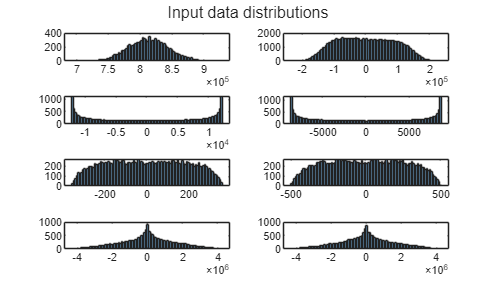

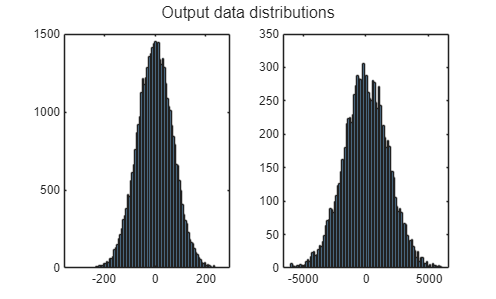

ans = 278.8795

ie_max = 326.7768

ix_max = 357.1429

iy_max = 500

is_max = 571.4286

vo_max = 6000

vB_max = 12000

VCdiff = 0.1000

C = 0.0050

vc_mean_ref = 18000

Xmax = 1.0e+06 *

    0.8100
    0.1701
    0.1701
    0.1701
    0.1701
    0.1701
    0.1701
    0.1701
    0.1701
    0.1701
    0.0121
    0.0121
    0.0087
    0.0087
    0.0004


Ymax = 1.0e+03 *

    1.1429
    1.1429
    1.1429
    1.1429
    6.0000


ans =           22       10482


ans =            5       10482


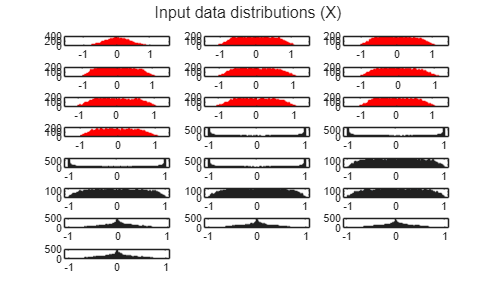

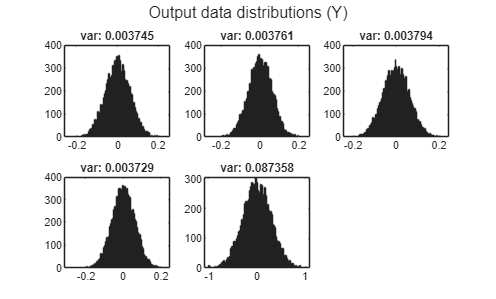

run('DataPreparation.mlx');

# Data

function [ie, iz, is, ixy, iB] = generate_data
    A = [1  1  1  0  0  0  0  0  0;
         0  0  0  1  1  1  0  0  0;
         0  0  0  0  0  0  1  1  1;
        -1  0  0 -1  0  0 -1  0  0;
         0 -1  0  0 -1  0  0 -1  0;
         0  0 -1  0  0 -1  0  0 -1];
    pinvA = pinv(A);
    N     = null(A, 'rational');
    Ax = 7000;
    Ay = 5000;
    [ix_max, iy_max, ~, ~, ~, ~] = max_values(Ax, Ay);

    ie = 300*(2*rand(4, 1)-1);
    iz = N*ie;
    gx = rand * 2*pi;
    ixa = ix_max * sin(gx);
    ixb = ix_max * sin(gx-2*pi/3);
    ixc = ix_max * sin(gx+2*pi/3);
    gy = rand * 2*pi;
    iya = iy_max * sin(gy);
    iyb = iy_max * sin(gy-2*pi/3);
    iyc = iy_max * sin(gy+2*pi/3);
    ixy = [ixa; ixb; ixc; iya; iyb; iyc];
    iB = pinvA * ixy;
    is = iB + iz;
end

[ie, iz, is, ixy, iB] = generate_data

ie =   188.8342
  243.4752
 -223.8079
  248.0255


iz =   456.5270
   34.9737
 -491.5007
 -432.3094
  188.8342
  243.4752
  -24.2176
 -223.8079
  248.0255


is =   272.6777
  112.9963
 -649.6154
 -414.7342
  468.2813
  286.7850
 -145.5500
  -83.2684
  152.4276


ixy =  -263.9413
  340.3321
  -76.3909
  287.6065
 -498.0092
  210.4028


iB =  -183.8493
   78.0226
 -158.1147
   17.5752
  279.4471
   43.3098
 -121.3324
  140.5395
  -95.5979



original = struct();
original.ie = ie;
original.iz = iz;
original.is = is;
original.ixy = ixy;

function compare(original, optimal_projection, projection, name)
    disp(strcat(['Comparation of projection method: ', name]))
    disp('  Original | Optimal | Actual')
    disp('ie')
    disp([original.ie, optimal_projection.ie, projection.ie]);
    % disp('iz')
    % disp([original.iz, optimal_projection.iz, projection.iz]);
    disp('is')
    disp([original.is, optimal_projection.is, projection.is]);
    disp('ixy')
    disp([original.ixy, optimal_projection.ixy, projection.ixy]);
end

# Constraints


$$-\check{i_s}\leq i_B+N\cdot i_\varepsilon\leq\hat{i_s}$$


Define matrices


$$A_c\cdot i_\varepsilon\leq b_c$$


Ac = [N; -N];
bc = [is_max - iB; is_max + iB];
pinvAc = pinv(Ac);

Polytope properties

analyzePolytope(Ac, bc);


=== Polytope Properties ===
Dimensión afín   : 4
Acotado          : Sí
Número de facetas: 18
Número de vértices: 64
Número de aristas : 423
Volumen/Área     : N/A para dimensión >3
Centroide        : [ -37.06 18.56 13.23 -5.375 ]
ChebyCenter      : [ 10.54 112.7 149.5 -97.37 ]
Inradius         : 281.4
Diámetro         : 2286



Visualize slice

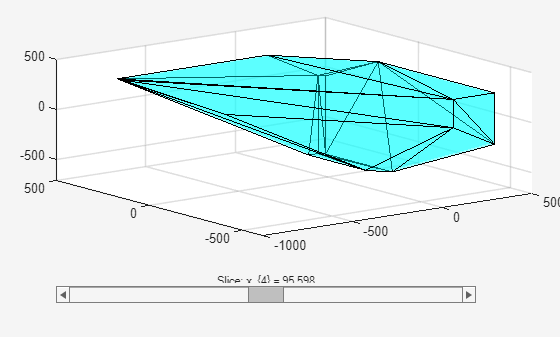

freeDim = 4;
visualizeSlice3D(Ac, bc, freeDim);

## Active set solver

H   = eye(4);
f   = -ie;
options = mpcActiveSetOptions;
[ie_proj, exitflag, iA, lambda] = mpcActiveSetSolver(H, f, Ac, bc, zeros(0, 4), zeros(0, 1), false(18, 1), options);
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

exitflag

exitflag = int32
2


optimal_projection = struct();
optimal_projection.ie = ie_proj;
optimal_projection.iz = iz_proj;
optimal_projection.is = is_proj;
optimal_projection.ixy = ixy_proj;

% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Hardnet-aff

ie_correction = pinvAc * max(0, Ac * ie - bc);
ie_proj = ie - ie_correction;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'HardNet-Aff')

Comparation of projection method: HardNet-Aff
  Original | Optimal | Actual
ie
  188.8342  188.8342  193.1779
  243.4752  204.3818  234.7877
 -223.8079 -223.8079 -219.4642
  248.0255  208.9321  239.3381
is
  272.6777  194.4909  263.9903
  112.9963  112.9963  104.3089
 -649.6154 -571.4286 -632.2405
 -414.7342 -375.6408 -410.3904
  468.2813  468.2813  472.6250
  286.7850  247.6916  278.0975
 -145.5500 -106.4566 -141.2063
  -83.2684  -83.2684  -78.9247
  152.4276  113.3342  143.7402
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 60.8119

## Scalar clipping

Ac_ie = Ac * ie;
alpha_i = inf(size(Ac_ie));
pos = Ac_ie > 0;            
alpha_i(pos) = bc(pos) ./ Ac_ie(pos);
alpha = min(1, min(alpha_i));
ie_proj = alpha * ie;
iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Scalar Clipping')

Comparation of projection method: Scalar Clipping
  Original | Optimal | Actual
ie
  188.8342  188.8342  158.7949
  243.4752  204.3818  204.7437
 -223.8079 -223.8079 -188.2051
  248.0255  208.9321  208.5702
is
  272.6777  194.4909  200.0545
  112.9963  112.9963  107.4328
 -649.6154 -571.4286 -571.4286
 -414.7342 -375.6408 -345.9634
  468.2813  468.2813  438.2420
  286.7850  247.6916  248.0535
 -145.5500 -106.4566 -141.6976
  -83.2684  -83.2684  -47.6656
  152.4276  113.3342  112.9723
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Cimmino original

Mean of constraint violations

K      = 5;         % Number of iterations
lambda = 1.5;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
n2 = sum(Ac.^2, 2); % Precalculate squared norm of each row of Ac
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0) ./ n2;
    d = (Ac.' * V) / size(Ac, 1);
    ie_proj = ie_proj - lambda * d;
end
toc

Elapsed time is 0.006403 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Mean')

Comparation of projection method: Cimmino Mean
  Original | Optimal | Actual
ie
  188.8342  188.8342  188.8342
  243.4752  204.3818  229.6841
 -223.8079 -223.8079 -223.8079
  248.0255  208.9321  234.2345
is
  272.6777  194.4909  245.0956
  112.9963  112.9963  112.9963
 -649.6154 -571.4286 -622.0332
 -414.7342 -375.6408 -400.9431
  468.2813  468.2813  468.2813
  286.7850  247.6916  272.9939
 -145.5500 -106.4566 -131.7590
  -83.2684  -83.2684  -83.2684
  152.4276  113.3342  138.6366
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 50.6047

## Cimmino modified

Max of constraint violations

K      = 3;         % Number of iterations
lambda = 1;         % Relaxation factor
ie_proj = ie;       % Initialize projection
tic
for k = 1:K
    R = Ac * ie_proj - bc;
    V = max(R, 0);
    [vmax, idx_max] = max(V);
    if vmax <= 0
        break;
    end
    ai    = Ac(idx_max, :)';
    ri    = ai' * ie_proj - bc(idx_max);
    ie_proj = ie_proj - lambda * (ri / (ai' * ai)) * ai;
end
toc

Elapsed time is 0.013637 seconds.


iz_proj = N * ie_proj;
is_proj = iB + iz_proj;
ixy_proj = A * is_proj;

projection = struct();
projection.ie = ie_proj;
projection.iz = iz_proj;
projection.is = is_proj;
projection.ixy = ixy_proj;

compare(original, optimal_projection, projection, 'Cimmino Max')

Comparation of projection method: Cimmino Max
  Original | Optimal | Actual
ie
  188.8342  188.8342  188.8342
  243.4752  204.3818  204.3818
 -223.8079 -223.8079 -223.8079
  248.0255  208.9321  208.9321
is
  272.6777  194.4909  194.4909
  112.9963  112.9963  112.9963
 -649.6154 -571.4286 -571.4286
 -414.7342 -375.6408 -375.6408
  468.2813  468.2813  468.2813
  286.7850  247.6916  247.6916
 -145.5500 -106.4566 -106.4566
  -83.2684  -83.2684  -83.2684
  152.4276  113.3342  113.3342
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Dykstra

K        = 1;         % Número de iteraciones externas
lambda   = 1;         % Factor de relajación (p.ej. 1.2)
ie_proj  = ie;        % Inicializa la proyección
n2       = sum(Ac.^2, 2);    % Precalcula ||a_i||^2 para cada restricción
p        = zeros(size(Ac));  % Correcciones acumuladas, una fila por restricción

tic
for k = 1:K
    for i = 1:size(Ac, 1)
        ai      = Ac(i, :).';
        bi      = bc(i);
        aux     = ie_proj + p(i, :).';
        ri      = ai.' * aux - bi;
        x_new   = aux - lambda * (ri / n2(i)) * ai * (ri > 0);
        p(i, :) = (aux - x_new).';
        ie_proj = x_new;
    end
end
toc

Elapsed time is 0.004772 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Dykstra')

Comparation of projection method: Dykstra
  Original | Optimal | Actual
ie
  188.8342  188.8342  188.8342
  243.4752  204.3818  204.3818
 -223.8079 -223.8079 -223.8079
  248.0255  208.9321  208.9321
is
  272.6777  194.4909  194.4909
  112.9963  112.9963  112.9963
 -649.6154 -571.4286 -571.4286
 -414.7342 -375.6408 -375.6408
  468.2813  468.2813  468.2813
  286.7850  247.6916  247.6916
 -145.5500 -106.4566 -106.4566
  -83.2684  -83.2684  -83.2684
  152.4276  113.3342  113.3342
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0

## Douglas Peaceman Rachford

K = 1;
lambda = 1;               % relajación (normalmente 1)
ie_proj = ie;                   % estado

tic
for k = 1:K
    x_old = ie_proj;
    % reflejar sucesivamente por cada semiespacio
    for i = 1:size(Ac, 1)
        ai      = Ac(i, :).';
        bi      = bc(i);
        ri      = ai.' * ie_proj - bi;
        p       = ie_proj - (ri / (ai.' * ai)) * ai * (ri > 0);
        r       = 2 * p - ie_proj;
        ie_proj = ie_proj + lambda * (r - ie_proj);
    end
    % opcional: media con x_old para estabilidad DR
    ie_proj = 0.5 * (ie_proj + x_old);
end
toc

Elapsed time is 0.006253 seconds.



iz_proj   = N * ie_proj;
is_proj   = iB + iz_proj;
ixy_proj  = A * is_proj;

projection = struct();
projection.ie   = ie_proj;
projection.iz   = iz_proj;
projection.is   = is_proj;
projection.ixy  = ixy_proj;

compare(original, optimal_projection, projection, 'Douglas Peaceman Rachford')

Comparation of projection method: Douglas Peaceman Rachford
  Original | Optimal | Actual
ie
  188.8342  188.8342  188.8342
  243.4752  204.3818  204.3818
 -223.8079 -223.8079 -223.8079
  248.0255  208.9321  208.9321
is
  272.6777  194.4909  194.4909
  112.9963  112.9963  112.9963
 -649.6154 -571.4286 -571.4286
 -414.7342 -375.6408 -375.6408
  468.2813  468.2813  468.2813
  286.7850  247.6916  247.6916
 -145.5500 -106.4566 -106.4566
  -83.2684  -83.2684  -83.2684
  152.4276  113.3342  113.3342
ixy
 -263.9413 -263.9413 -263.9413
  340.3321  340.3321  340.3321
  -76.3909  -76.3909  -76.3909
  287.6065  287.6065  287.6065
 -498.0092 -498.0092 -498.0092
  210.4028  210.4028  210.4028



% Max constraint violation original ie
max(Ac*ie - bc)

ans = 78.1868

% Max constraint violation projected ie
max(Ac*ie_proj - bc)

ans = 0